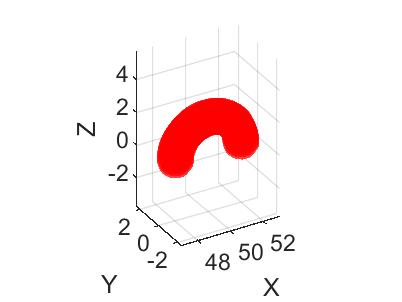

xgrid = 100;
ygrid = 100;
zgrid = 100;

[x, y, z] = meshgrid(1:xgrid, 1:ygrid, 1:zgrid);

figure;
hold on;

% arch params
arch_radius = 2; % arch radius
base_radius = 2; % base radius
arch_height = 30;
arch_center = [xgrid/2, ygrid/2, 0]; % arch center


% plotting spheres
n_spheres = 50; % number of spheres to approximate the arch
theta = linspace(0, pi, n_spheres); % Angle range for the arch

for i = 1:n_spheres
    % centers for spheres
    x_sphere = arch_radius * cos(theta(i)) + arch_center(1);
    z_sphere = arch_radius * sin(theta(i)) + arch_center(3);
   
    curr_height = arch_height * (1 - sin(theta(i)));
    % making larger spheres at top and smaller ones on the bottom?
    % curr_radius = .3*((arch_radius - base_radius) / arch_height * curr_height + base_radius);
    curr_radius = 1;
    % plot
    [x_sphere_mesh, y_sphere_mesh, z_sphere_mesh] = sphere(10); % N is resolution basically
    x_sphere_mesh = x_sphere_mesh * curr_radius + x_sphere;
    y_sphere_mesh = y_sphere_mesh * curr_radius;
    z_sphere_mesh = z_sphere_mesh * curr_radius + z_sphere; % Adjust z-coordinates
    surf(x_sphere_mesh, y_sphere_mesh, z_sphere_mesh, 'FaceColor', 'red', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
end

xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;
axis equal;

% Set viewing angle
view(-30, 30); % Adjust azimuth and elevation as needed


% PRM time?? 
num_points = 100;
points_x = randi([1, xgrid], 1, num_points);
points_y = randi([1, ygrid], 1, num_points);
points_z = randi([1, zgrid], 1, num_points);

% store whether each point is inside a sphere
inside_sphere = false(1, num_points);

for p = 1:num_points
    % check the distance from the point to each sphere
    for i = 1:n_spheres
        % center of the current sphere
        x_sphere = arch_radius * cos(theta(i)) + arch_center(1);
        y_sphere = arch_radius * sin(theta(i)) + arch_center(2);
        
        % distance from the point to the center of the current sphere
        distance = sqrt((points_x(p) - x_sphere)^2 + (points_y(p) - y_sphere)^2 + (points_z(p) - arch_center(3))^2);
        
        % check whether distance is less than the radius of the sphere
        if distance <= 10 % adjust the radius for a small tolerance
            inside_sphere(p) = true;
            break; % if the point is inside one sphere, no need to check other spheres
        end
    end
end
% something is wrong here lol its not marking any points as inside sphere 
inside_sphere

inside_sphere = 1×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


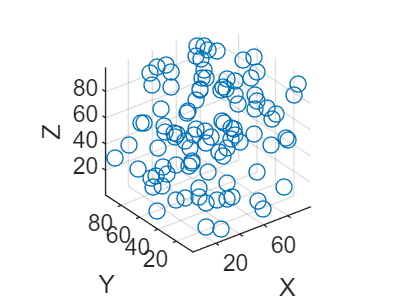

% Plot the random points and color them based on whether they are inside a sphere
figure;
scatter3(points_x, points_y, points_z);
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;
axis equal;